# Actividad 4

Raúl Correa Ocañas

A01722401

9 de junio de 2023

clc
clear

## Regresión Lineal

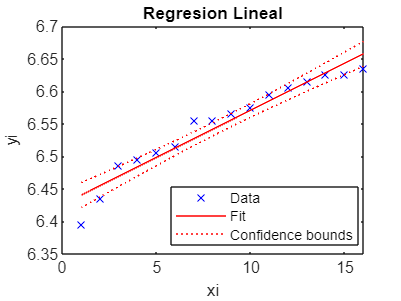

table1 = readtable("datos_regresion.csv");
reg = fitlm(table1);

figure(1)
plot(reg)
title("Regresion Lineal")

## Regresión No Lineal

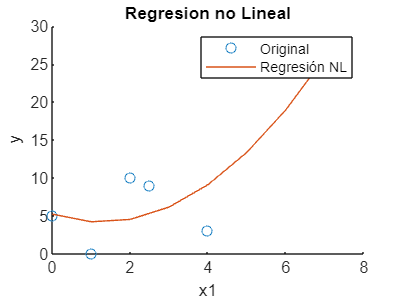

table2 = readtable("datos_regresion_multiple.csv");
x = table2.x1;
y_orig = table2.y;

degree = 2;

p = polyfit(x, y_orig, degree);

y_fit = polyval(p, min(x):1:max(x));

figure(2)

a1 = scatter(x, y_orig);
hold on
a2 = plot(min(x):1:max(x), y_fit);
hold off

legend([a1,a2], "Original", "Regresión NL")
xlabel('x1')
ylabel('y')
title('Regresion no Lineal')

## Regresion Multiple

x1 = table2.x1;
x2 = table2.x2;
y1 = table2.y;

X = [ones(size(x1)) x1 x2 x1.*x2];
b = regress(y1,X);

b =     5.0000
    4.0000
   -3.0000
    0.0000


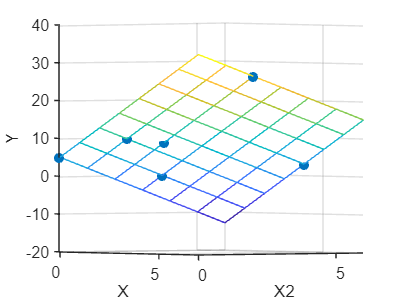


scatter3(x1,x2,y1, 'filled')
hold on
x1fit = min(x1):1:max(x1);
x2fit = min(x2):1:max(x2);
[X1FIT,X2FIT] = meshgrid(x1fit,x2fit);
YFIT = b(1) + b(2)*X1FIT + b(3)*X2FIT + b(4)*X1FIT.*X2FIT;
mesh(X1FIT,X2FIT,YFIT)
xlabel('X')
ylabel('X2')
zlabel('Y')
view(50,1)
hold off